# **Mobile robot kinematics**

The kinematics of a robot depends on the configuration of its wheels and the type of these. The simplest is an differential configuration.

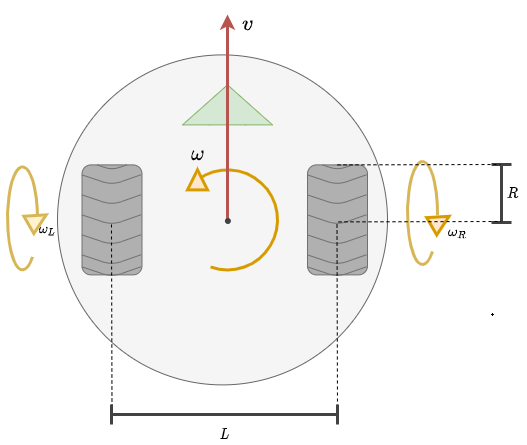

In this configuration We have two questions.

- Given $\omega_R$ and $\omega_L$. Wich are the linear $v$ and angular $\omega$ velocities?

- The robot needs to move with specific $\omega$ and $v$ velocities. Which are the angular velocities $\omega_R$ and $\omega_L$ to achieve that?

Let´s create  a Differential mobile robot by define an DifferentialDrive object.

R = 0.1; % Wheel radius [m]
L = 0.5; % Wheelbase [m]
mobileRobot = DifferentialDrive(R,L)

mobileRobot =   DifferentialDrive with properties:

    wheelRadius: 0.1000
      wheelBase: 0.5000


-----------------------------------------------------------------------------------------------------------------

To answer the** first** question, You need solve forward kinematics as shown below:


$$v=\frac{R}{2}{\left(\omega_R +\omega_L \right)},\ \ \;\;\;\;\;\;\;\omega =\frac{R}{L}{\left(\omega_R -\omega_L \right)}$$


We can solve forward kinematics by the function  **forwardKinematics**

wL = 1.2; % [rad/s]
wR = -0.4; % [rad/s]
[v,w] = forwardKinematics(mobileRobot,wL,wR)

v = 0.0400

w = -0.3200

-----------------------------------------------------------------------------------------------------------------

To answer the **second** question, You need solve inverse kinematics as shown below:


$$\omega_L =\frac{1}{R}{\left(v-\frac{\omega L}{2}\right)},\ \ \;\;\;\omega_R =\frac{1}{R}{\left(v+\frac{\omega L}{2}\right)}$$


We can  solve inverse kinematics by the function  **inverseKinematics**

v = 0.3;
w = 0.4;
[wL,wR] = inverseKinematics(mobileRobot,v,w)

wL = 2.0000

wR = 4